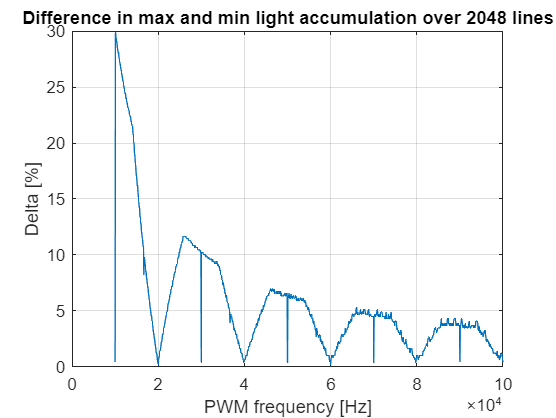

% variables
freq_LSC = 10000;
freq_line_light = linspace(10000, 100000, 1000);
duty_LSC = 50;
duty_line_light = 30;
num_periods = 2048;
time_res = 1000000;
offset = 0;
figure

delta = zeros(length(freq_line_light), 1);

% calculate time vector
t = linspace(0, num_periods/freq_LSC, time_res);

% calculate offset index
offset_index = round((offset/100)*(time_res/num_periods));

for y = 1:length(freq_line_light)
    % calculate PWM functions
    fun_LSC = PWM(freq_LSC, 0, 1, duty_LSC, t);
    fun_line_light = PWM(freq_line_light(y), offset_index, 1, duty_line_light, t);
    
    % calculate average voltage for every period
    exp_value = zeros(num_periods, 1);
    for i = 1:num_periods
        cum_val = 0;
        for n = floor(i*(time_res/num_periods)-(time_res/num_periods)) + 1:floor(i*(time_res/num_periods))
            cum_val = cum_val + fun_LSC(n)*fun_line_light(n);
        end
        exp_value(i) = cum_val/(time_res/num_periods);
    end
    
%     plot(0:length(exp_value)-1, exp_value)
%     hold on
%     ylim([0, 1])
    %pause(0.5)
    delta(y) = (max(exp_value) - min(exp_value))*100;
end

hold off
plot(freq_line_light, delta)
grid on
ylabel("Delta [%]")
xlabel("PWM frequency [Hz]")
title("Difference in max and min light accumulation over 2048 lines")